# **demo01 of Im2mesh package**

demo01 - Demonstrate function im2mesh, which use [MESH2D](https://github.com/dengwirda/mesh2d) as mesh generator.

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com   [Project website](https://github.com/mjx888/im2mesh)   [List of demo](https://mjx888.github.io/im2mesh_demo_html/demo_list.html)

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package. No need to install any MATLAB toolboxes when running this demo.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## im2mesh

Let's start demo01. We'll demostate the usage of function im2mesh.

Import image.

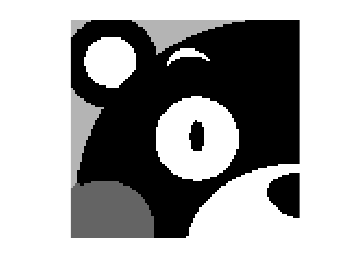

im = imread('kumamon.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Show the grayscale levels in the image

intensity = unique( im ); 
intensity

intensity = 4×1 uint8 column vector
     0
   100
   180
   255


Let's use function im2mesh to generate meshes based on the kumamon image. We will use default settings. Note that function im2mesh has incorporated the workflow that you saw in im2mesh_GUI: extract polygonal boundaries from image, search & label control points, smooth boundary, simplify boundary, select phase, and generate mesh.

[ vert, tria, tnum ] = im2mesh( im );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                149                231
         10                168                526
         12                168                530


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                257                231
         10                271               1507
         17                283               1956


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                 37               1944



Function im2mesh has 3 ouptut variables: vert, tria, tnum. They defines **linear elements** of generated triangular mesh.

vert - Node data. N-by-2 array.

tria - Node numbering for each triangle. M-by-3 array.

tnum - Label of material phase. P-by-1 array.

We can plot the mesh using function plotMeshes.

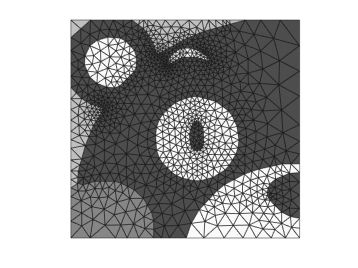

plotMeshes( vert, tria, tnum )

## Mesh quality

We can use function tricost to check the mesh quality. Function tricost is written by by Darren Engwirda.

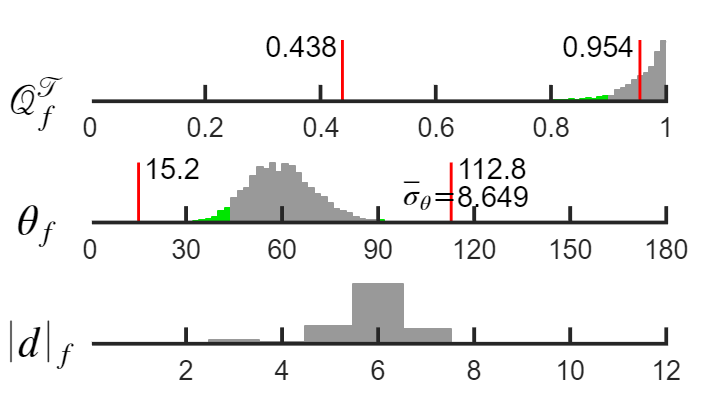

tricost( vert, tria );

We can get the mean value of Q.

mean(triscr2( vert, tria ))

ans = 0.9544

Wonderful! Let's check the total number of triangles in the mesh.

size( tria, 1 )

ans = 1944

That's a lot of triangles. 

## Change parameter

We can change the parameters of function im2mesh to see whether it help to reduce the number of triangles. 

opt = [];               % initialize. opt is a structure array.
opt.tolerance = 1;      % default value for opt.tolerance is 0.3

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                 97                125
          8                108                213


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                152                125
         10                170                670
         12                170                676


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------



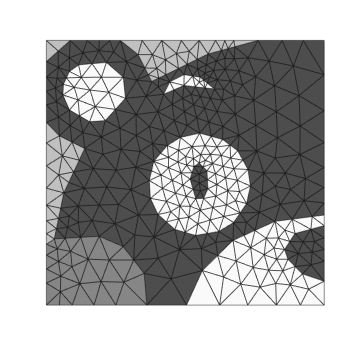

plotMeshes( vert, tria, tnum )

size( tria, 1 )

ans = 670

Now, the number of triangles decreases a lot. That's great.

## Parameters of function im2mesh

As I showed before, there're two ways to call function im2mesh.

Variable opt means options. It's a structure array used to stored input parameters for function im2mesh. We can take a look at the default value of opt.

You don't need to memorize the names of these parameters. The meaning of these parameters are listed the file "im2mesh.m" and "Im2mesh functions and parameters.pdf". Please refer to "Im2mesh_GUI Tutorial.pdf" about how to choose the value of these parameters. You can change the default values by editting the sub-function setOption in "im2mesh.m".

## Quadratic element

Function im2mesh can also generate quadratic element via the following syntax.

Ouput variables - vert, tria, tnum define **linear elements.**

Ouput variables - vert2, tria2, tnum define **quadratic elements.**

Their meanings are as follows.

vert - Node data. N-by-2 array.

tria - Node numbering for each triangle. M-by-3 array.

tnum - Label of material phase. P-by-1 array.

vert2 - Node data (2nd order element). P-by-2 array. Due to new vertices, the length of vert2 is much longer than vert.

tria2 - Node numbering for each triangle (2nd order element). M-by-6 array.

You can also plot mesh using function plotMeshes, or eveluate mesh quality using function tricost.

## Example 1

Let's show some examples with different opt.

% example 1
opt = [];               % reset opt
opt.tolerance = 1e-10;  % no polyline simplification

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                702               1309
         10                730               1685
         20                757               3636
         20                757               3636


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                867               1309
         16                883               1309
         20                886               5988
         30                887              10635
         31                887              10637


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -----------

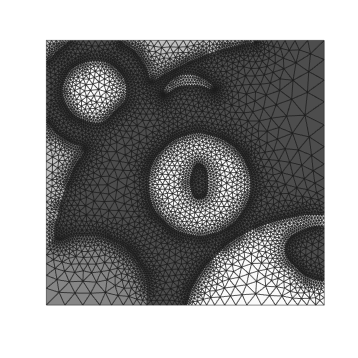

plotMeshes( vert, tria, tnum );

## Example 2

% example 2
opt = [];                       % reset opt
opt.tolerance = 1;
opt.select_phase = [1 2 4];     % select phase for meshing

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          3                 85                117
          7                 92                185


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                133                117
         10                146                602
         12                147                609


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                  0                607



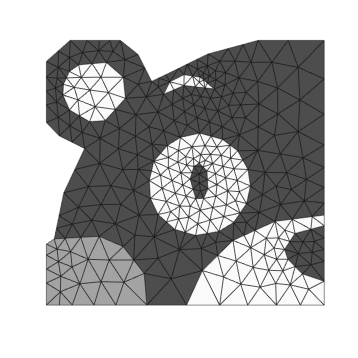

plotMeshes( vert, tria, tnum );

## Example 3

What if we don't need to generate mesh and we want to check the simplified polygonal boundary?

In this special case, we can set "opt.tf_mesh = false;". It means we do not generate mesh. We will use this method in other demos.

% example 3
opt = [];                       % reset opt
opt.tolerance = 1;
opt.select_phase = [1 2 4];     % select phase for meshing
opt.tf_mesh = false;            % do not generate mesh

bounds = im2mesh( im, opt );

bounds is the simplified polygonal boundaries. We use function plotBounds to plot it.

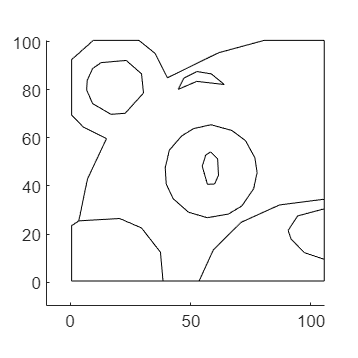

plotBounds(bounds);

We can plot the polygons with a face color. Please refer to the following link for how to set face color: [https://www.mathworks.com/help/matlab/ref/polyshape.plot.html](https://www.mathworks.com/help/matlab/ref/polyshape.plot.html)

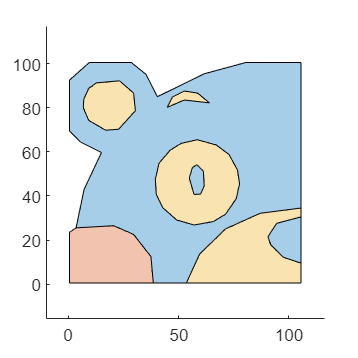

% convert to a cell array of polyshapes
psCell = bound2polyshape(bounds);

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot( psCell{i} );
end
hold off

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo